# The Gauntlet Challenge

**Authors: Dexter Friis-Hecht, Dokyun Kim, Ellen Sun**

Using the data from the Neato's LiDAR sensor, create a map of the gauntlet. Then, program it to safely navigate itself to the 'Barrel of Benevolnce' while avoiding all obstacles. 

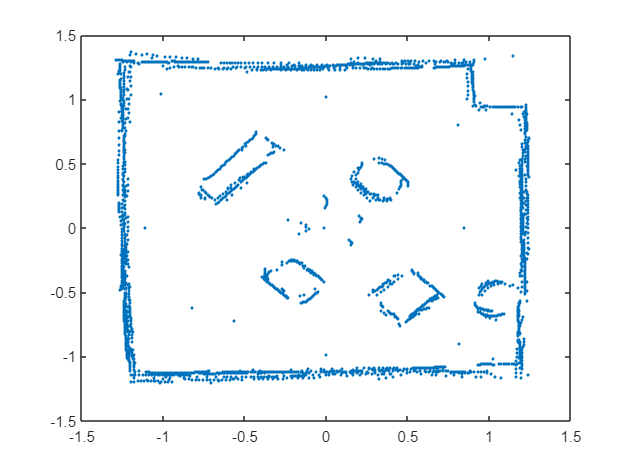

warning('off')
close all, clear all, clc

% Load LiDAR data
load('map.mat')
data_cart = all_points';
% Convert cartesian to polar
[t,rho] = cart2pol(data_cart(:,1),data_cart(:,2));
data = [rho rad2deg(t)];
figure()
plot(data_cart(:,1),data_cart(:,2),".")
hold on;

## RANSAC

!!! Re-run previous section before re-running this section !!!

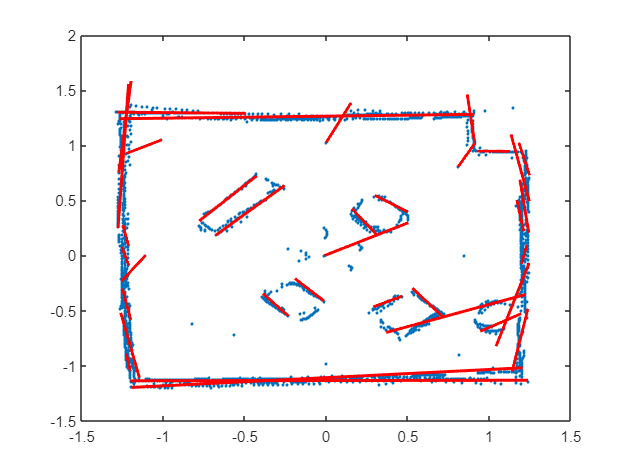

% Initialize array
m_array = ones(35,1);
b_array = ones(35,1);
ep1s = ones(35,1);
ep2s =ones(35,1);

iter = 35;
for i = 1:iter
    % Do RANSAC 'iter' times
    [m_b,ends,inlier,outlier,bestfit_point,polar]=find_RANSAC(data,0.03,10000);
    m_array(i) = m_b(1);
    b_array(i) = m_b(2);
    ep1s(i)=ends(1,1);
    ep2s(i)=ends(2,1);

    % Plot line
    x = linspace(ends(1,1),ends(2,1));
    y = m_b(1)*x+m_b(2);
    plot(x,y,'r',LineWidth=2)

    % Remove inliers, repeat RANSAC with new data
    [t,rho]=cart2pol(outlier(:,1),outlier(:,2));
    data = [rho rad2deg(t)];
end
hold off;

## Potential Fields

pots = []


pots =

     []



for i = 1:20
% Potential field for lines identified by RANSAC
    m = m_array(i);
    b = b_array(i);
    ep1 = ep1s(i);
    ep2 = ep2s(i);
    [potential,Xp,Yp]=line_potential(m,b,ep1,ep2);
    
    if i == 1
        X = Xp;
        Y = Yp;
        pots = potential;
    else
        pots = pots + potential;
    end
end

## Account for Error

%pot for missing line
x1=-0.455;
y1=0.747;
x2=-0.263;
y2=0.515;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,X,Y] = line_potential(new_m,new_b,x1,x2);
pots_test = pots + pot;

%pot for other missing line
x1=-0.173412;
y1=-0.36;
x2=-0.305;
y2=-0.533;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,X,Y] = line_potential(new_m,new_b,x1,x2);
pots_test = pots_test + pot;

%pot for top wall line
x1=-1.2625;
y1=1.075;
x2=1.15;
y2=1.1;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,X,Y] = line_potential(new_m,new_b,x1,x2);
pots_test = pots_test + pot;

%pot for left wall line
x1=-1.2875;
y1=1.05;
x2=-1.2375;
y2=-1.3;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,X,Y] = line_potential(new_m,new_b,x1,x2);
pots_test = pots_test + pot;

%pot for right wall line
x1=1.225;
y1=1.0875;
x2=1.275;
y2=-1.275;


a = y1-y2;
b = -(x1-x2);
c = x1*y2-x2*y1;


new_m = -a/b;
new_b = -c/b;
[pot,X,Y] = line_potential(new_m,new_b,x1,x2);
pots_test = pots_test + pot;

## Barrel of Benevolence

% Adds a circle to where BoB should be
[pot_circ,x,y] = circ_potential(-1.1,0.5,0.14);
pots_test = pots_test+pot_circ;

point_pot = []


point_pot =

     []



for i = 1:length(X)
    x = X(1,i);
    for j = 1:length(Y)
        y = Y(j, 1);
        point_pot(j,i) = -700 * (log(sqrt((x-0.8375).^2+(y-.5).^2)) + log(sqrt((x-0.4625).^2+(y-.05).^2)) + log(sqrt((x-0.65).^2+(y-.2375).^2)) + log(sqrt((x-0.05).^2+(y+.5).^2)) + log(sqrt((x-.2875).^2+(y+.35).^2)));
    end
end

pots_pt = pots_test + point_pot;


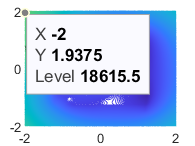

pots_final = 1.0e+04 *

    1.5919    1.5861    1.5802    1.5743    1.5683    1.5624    1.5565    1.5505    1.5446    1.5386    1.5326    1.5267    1.5207    1.5147    1.5087    1.5027    1.4966    1.4906    1.4846    1.4786    1.4725    1.4665    1.4604    1.4544    1.4484    1.4423    1.4363    1.4302    1.4242    1.4181    1.4121    1.4060    1.4000    1.3940    1.3879    1.3819    1.3759    1.3699    1.3639    1.3579    1.3519    1.3460    1.3400    1.3340    1.3281    1.3222    1.3163    1.3104    1.3045    1.2987
    1.5881    1.5821    1.5762    1.5703    1.5643    1.5583    1.5524    1.5464    1.5404    1.5344    1.5283    1.5223    1.5163    1.5102    1.5042    1.4981    1.4921    1.4860    1.4799    1.4739    1.4678    1.4617    1.4556    1.4495    1.4434    1.4373    1.4312    1.4251    1.4190    1.4129    1.4068    1.4007    1.3946    1.3886    1.3825    1.3764    1.3703    1.3643    1.3582    1.3522    1.3461    1.3401    1.3341    1.3281    1.3221    1.3161    1.3101    1

figure()
hold on;
contour(X,Y,pots_pt,500)
[dx,dy] = gradient(pots_pt);
axis([-2 2 -2 2])
hold off

save("pots.mat", "pots_final", "X", "Y")